# 数值计算 上机作业 Chapter7

### 李宇豪    21305412

对于函数


$$f(x)=x^{-1}\cos(x^{-1}\ln x)$$


f = @(x) x.^-1 .* cos(x.^-1 .* log(x));

我们首先观察一下函数在 $[0,1]$ 上的形状

xx = linspace(0, 1, 1000);
plot(xx, f(xx))

## 直接使用Matlab 的 integral 函数求解积分

format long
integral(f, 0, 1, 'AbsTol' ,1e-10, 'RelTol',0)

注意到，函数 $f(x)$ 在 $x=0$ 处看起来是不收敛的，如下所示

xx = linspace(1e-9, 1e-7, 1e3);
plot(xx, f(xx))

直接在 $[0,1]$ 上积分是不收敛的，因此考虑在接近 $x=0$ 处进行截断

经查阅文献，该积分结果的一个比较高的精度（15位）的数值为

standard = 0.323367431677778;

我们以这个结果为参考值，比较各个结果的误差。

I1 = integral(f, 1e-6, 1)
abs(I1 - standard)/standard

I2 = integral(f, 1e-5, 1)
abs(I2 - standard)/standard

I3 = integral(f, 1e-4, 1)
abs(I3 - standard)/standard

此时数值积分已经收敛，并且相对误差较小。

I4 = integral(f, 1e-3, 1)
abs(I4 - standard)/standard

如果截断值再增大，计算精度会下降。

## 将积分改写成级数后再进行计算

将积分改写为级数后进行计算，主要要考虑划分区间的问题。

从函数图像中可以看出，越靠近 0 处函数图像震荡的越激烈，余荫铠学长提供了一种思路是，根据函数的零点进行划分积分区间。

即根据方程 $\frac{\mathrm{ln}(x)}{x}=\frac{\pi}{2}-k\pi$的解划分区间。为了解这个超越方程，需要使用 Lambert W 函数，其定义为


$$W(t)\mathrm e ^{W(t)}=t$$


函数 $f(x)$ 的第 k 个零点为


$$x_k = \frac{W(k\pi-\frac{\pi}{2})}{k\pi-\frac{\pi}{2}}$$


采用这种划分方式，计算结果为

err = 1e-6;
I5 = sum2integral(err)
abs(I5 - standard)/standard 

采用这种方式，可以通过降低截止误差的方式不断提高计算精度（代价是运行时间不断增加）。

## 另一种处理方式

函数 $f(x)=x^{-1}\cos(x^{-1}\ln x)$ 的图像为

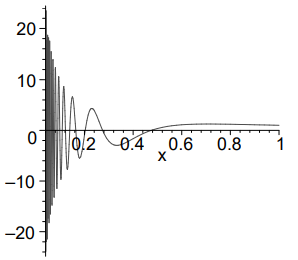

令 $t = \frac{1}{x}$，则原积分化为


$$I=\int_1^\infty t^{-1}\cos(t\ln t)dt$$


此时被积函数的图像为

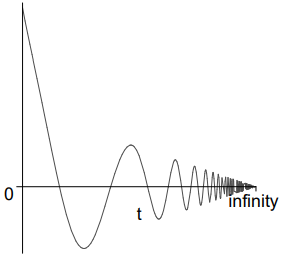

我们直接进行积分，看一下效果

g = @(t) t.^-1 .* cos(t.* log(t));
I6 = integral(g, 1, 1e6)
abs(I6 - standard)/standard 

I7 = integral(g, 1, 1e5)
abs(I7 - standard)/standard 

I8 = integral(g, 1, 1e4)
abs(I8 - standard)/standard 

可以看到，随着对正无穷的截断值的增大，计算误差也会增加。这是因为，随着 t 的增加，被积函数的震荡也会变得更加剧烈，函数的零点间距会愈加稠密，这也是不利于我们划分区间进行积分的。

再令 $u=t\ln t$，则积分化为


$$I=\int_0^\infty \frac{\cos(u)}{\frac{u}{W(u)}+u}du=\int_0^\infty \cos(u)f(u)du$$


其中， $f(u)=\frac{W(u)}{u[W(u)+1]}$， $W(u)$ 仍是Lambert W Function 

此时被积函数的图像为

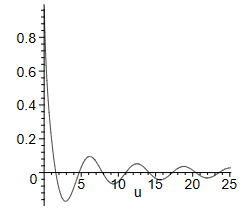

这种函数是我们想要的，有利于进行数值积分的被积函数。

对于这个在 $[0,+\infty)$ 上的积分，为了提高数值计算的精度，我们将其分为两部分


$$I=\int_0^\infty \cos(u)f(u)du=\int_0^\bar{u} \cos(u)f(u)du+\int_\bar{u}^\infty \cos(u)f(u)du=I_1+I_2$$


只要选取 $\bar{u}$ 为 $\pi$ 的整数倍， $I_1$ 是一个非常简单的积分。

实际上，如果 $\bar{u}$ 选取的足够大，我们甚至不用计算 $I_2$，比如选取 $\bar{u}=10000\pi$ 时

h1 = @(u) cos(u) .* lambertw(u) .* (u + u .* lambertw(u)).^-1
tic
I9 = integral(h1, 0, 10000*pi)
abs(I9 - standard)/standard 
toc

此时已经达到了 $10^{-9}$ 的精度，并且只用了 0.07 秒。如果采用上一小节的处理方式，据余荫铠学长说，要达到 $10^{-8}$ 的精度，代码需要运行5个小时。

至于 $I_2$ 部分的处理，略微有些麻烦，需要利用分部积分公式不断进行递推，文献[1]中有对这个处理方式的详细介绍。由于我们可以直接通过截断得到一个不错的精度，这里就不再折腾了。

## 参考文献

[1] Specht, Eckard & Wohlgemuth, Martin & Raab, Clemens & Gehlen, Lutz. (2002). How to solve the” A Hundred-dollar, Hundred-digit Challenge”. 

## 附：用到的函数定义

function intesum = sum2integral(err)
    f = @(x) x.^-1 .* cos(x.^-1 .* log(x));
    
    % 初始化
    k     = 1;
    x_max = 1;
    x_min  = lambertw(-pi*0.5+k*pi)./(-pi*0.5+k*pi);
    intecell = integral(f, x_min, x_max);
    intesum  = intecell;

    % 级数逼近
    while abs(intecell) > err
        k = k + 1;
        x_max = x_min;
        x_min = lambertw(-pi*0.5+k*pi)./(-pi*0.5+k*pi);
        intecell = integral(f, x_min, x_max, 'AbsTol' , err, 'RelTol',0);
        intesum  = intesum + intecell;
    end
    k
end